load ex1data1.txt
a=ex1data1

a =     6.1101   17.5920
    5.5277    9.1302
    8.5186   13.6620
    7.0032   11.8540
    5.8598    6.8233
    8.3829   11.8860
    7.4764    4.3483
    8.5781   12.0000
    6.4862    6.5987
    5.0546    3.8166


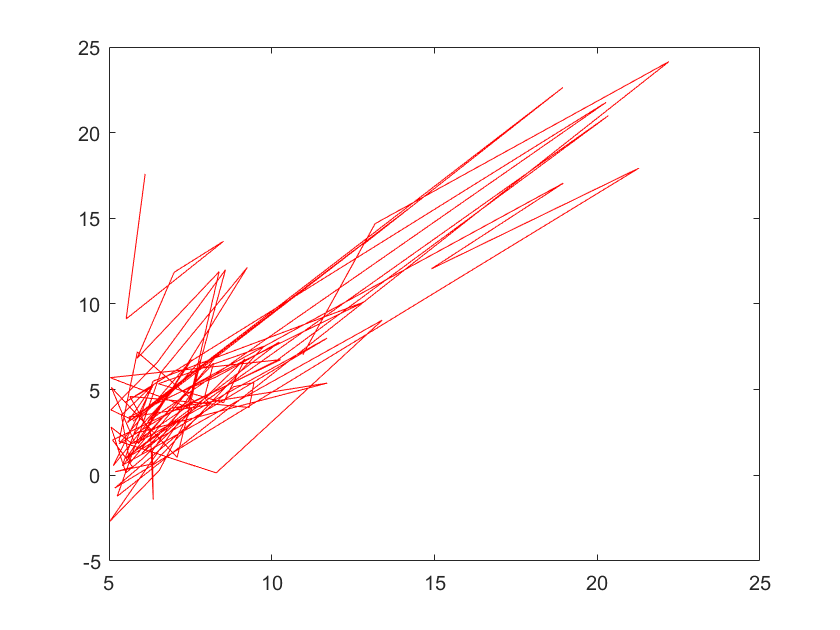

x=a(:,1);
y=a(:,2);

x(:,2)=x(:,1)

x =     6.1101    6.1101
    5.5277    5.5277
    8.5186    8.5186
    7.0032    7.0032
    5.8598    5.8598
    8.3829    8.3829
    7.4764    7.4764
    8.5781    8.5781
    6.4862    6.4862
    5.0546    5.0546


x(:,1)=ones(length(x),1)

x =     1.0000    6.1101
    1.0000    5.5277
    1.0000    8.5186
    1.0000    7.0032
    1.0000    5.8598
    1.0000    8.3829
    1.0000    7.4764
    1.0000    8.5781
    1.0000    6.4862
    1.0000    5.0546


theta=zeros(2,1);

aa=size(x)

aa =     97     2


bb=size(y)

bb =     97     1


cc=size(theta)

cc =      2     1



%theta(1)=1;%theta 0
%theta(2)=2;%theta 1
theta

theta =      0
     0



%cost function J
J=sum((x*theta-y).^2)/(2*length(y))

J = 32.0727

%note that over here the dimensions of theta and x dont matter. as long as
%they are correct in the data set, the formula is applicable

theta=zeros(2,1);
temp1=0

temp1 = 0

temp2=0

temp2 = 0

alpha = 0.01

alpha = 0.0100

j=[0]

j = 0

y

y =    17.5920
    9.1302
   13.6620
   11.8540
    6.8233
   11.8860
    4.3483
   12.0000
    6.5987
    3.8166


x

x =     1.0000    6.1101
    1.0000    5.5277
    1.0000    8.5186
    1.0000    7.0032
    1.0000    5.8598
    1.0000    8.3829
    1.0000    7.4764
    1.0000    8.5781
    1.0000    6.4862
    1.0000    5.0546


for iter=1:1500
    temp1=theta(1)-alpha*sum((x*theta-y).*x(:,1))/(length(y));
    temp2=theta(2)-alpha*sum((x*theta-y).*x(:,2))/(length(y));
    theta(1)=temp1;
    theta(2)=temp2;
    %for plotting cost funnction vs iterations
    j=[j, (sum((x*theta-y).^2)/(2*length(y)))];
    
end
theta(1)

ans = -3.6303

theta(2)

ans = 1.1664

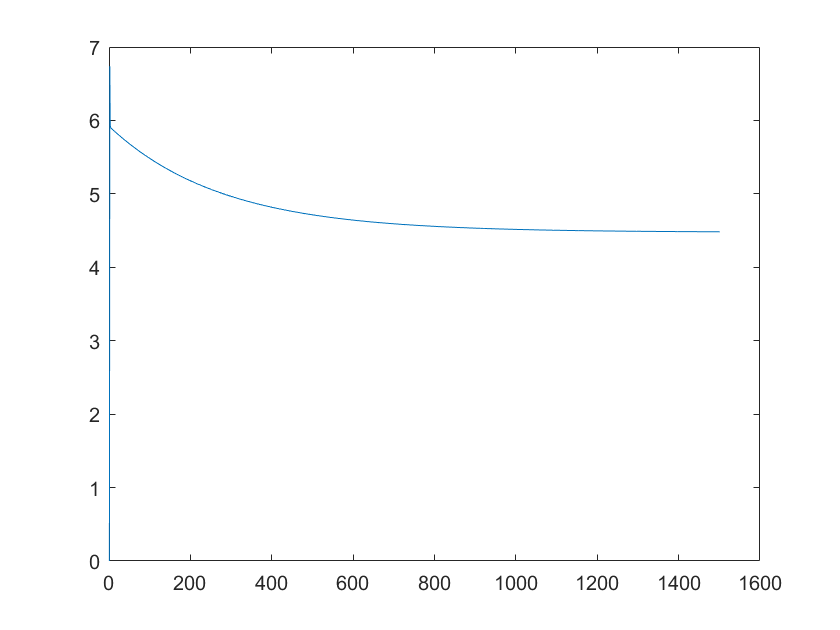

plot(j)

line=theta(1)+theta(2).*x(:,2)

line =     3.4963
    2.8170
    6.3055
    4.5380
    3.2044
    6.1472
    5.0899
    6.3749
    3.9350
    2.2652


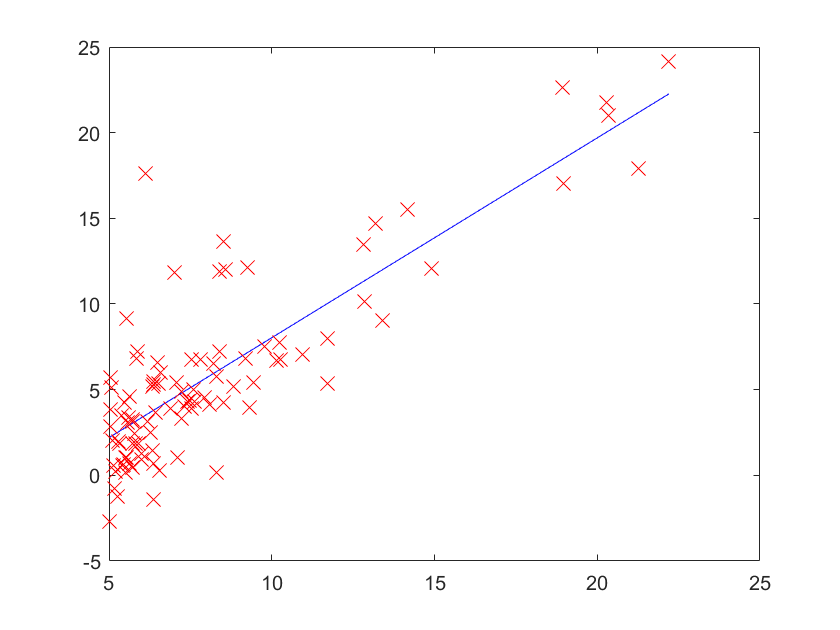

plot(x(:,2),line,'b')
hold on
plot(x(:,2), y, 'rx', 'MarkerSize', 10);
hold off

test section

regression(2, 0.01, 1500, 'b', x,y)
a=[1;2;3;4;5;6;7]

a =      1
     2
     3
     4
     5
     6
     7


b=[1;2;3;4;5;6;7]

b =      1
     2
     3
     4
     5
     6
     7


a.*b

ans =      1
     4
     9
    16
    25
    36
    49


   % ss=ones(34,3)
%sum(ss')